nrepeats = 3;
Data = zeros(nrepeats,8);
save 'C:\Users\verasonics\Documents\Vantage-4.8.4-2305101400\Barney\Verasonics-Acoustic-Tweezer\Measurements\ProbeImpedanceCheck\Data.mat' 'Data'
for n = 1:nrepeats
    save 'C:\Users\verasonics\Documents\Vantage-4.8.4-2305101400\Barney\Verasonics-Acoustic-Tweezer\Measurements\ProbeImpedanceCheck\n' 'n'
    ProbeZdata = ProbeImpedanceCheck(1);
    load 'C:\Users\verasonics\Documents\Vantage-4.8.4-2305101400\Barney\Verasonics-Acoustic-Tweezer\Measurements\ProbeImpedanceCheck\n.mat'
    disp(n)
    data = ProbeZdata.MeasZperCh([1,2,3,4,6,7,8,9]);
    load 'C:\Users\verasonics\Documents\Vantage-4.8.4-2305101400\Barney\Verasonics-Acoustic-Tweezer\Measurements\ProbeImpedanceCheck\Data.mat'
    Data(n,:) = data;
    save 'C:\Users\verasonics\Documents\Vantage-4.8.4-2305101400\Barney\Verasonics-Acoustic-Tweezer\Measurements\ProbeImpedanceCheck\Data.mat' 'Data'
end

     1

     2

     3



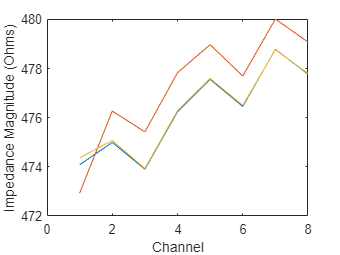

plot(Data')
xlabel('Channel')
ylabel('Impedance Magnitude (Ohms)')

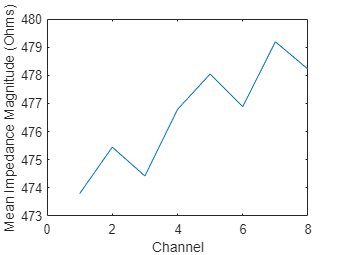

avrgData = mean(Data,1);
plot(avrgData)
xlabel('Channel')
ylabel('Mean Impedance Magnitude (Ohms)')